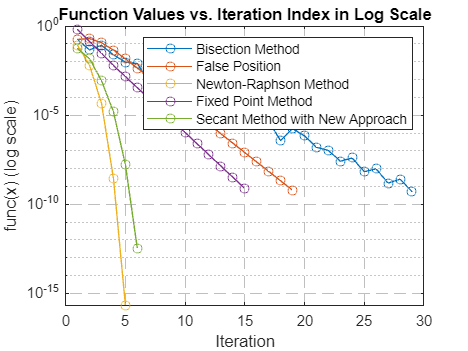

% Define the function
func = @(x) x .* cos(x) - 10 .* sin(x.^2 / 10);

% Define tolerance
ep = 1e-9;

% Bisection Method
u = 0.1;
v = 1;
iter = 0;
out = [];
while iter >= 0
    r = (u + v) / 2;
    out = [out, abs(func(r))];
    if abs(func(r)) <= ep
        break;
    else
        if func(u) * func(r) < 0
            v = r;
        elseif func(u) * func(r) > 0
            u = r;
        else
            break;
        end
    end
    iter = iter + 1;
end
x_bisection = 1:length(out); % X-values for Bisection Method

% False Position Method
u_ = 0.1;
v_ = 1;
iter_ = 0;
out_ = [];
while iter_ >= 0
    r_ = u_ - (func(u_) * (u_ - v_) / (func(u_) - func(v_)));
    out_ = [out_, abs(func(r_))];
    if abs(func(r_)) <= ep
        break;
    else
        if func(u_) * func(r_) < 0
            v_ = r_;
        elseif func(u_) * func(r_) > 0
            u_ = r_;
        else
            break;
        end
    end
    iter_ = iter_ + 1;
end
x_false_position = 1:length(out_); % X-values for False Position Method

% Newton-Raphson Method
deriv = @(x) cos(x) - sin(x) * x - x .* cos(x.^2 / 10) * 2;
x_0 = 1;
itern = 0;
out__ = [];
while itern >= 0
    x_1 = x_0 - func(x_0) / deriv(x_0);
    out__ = [out__, abs(func(x_1))];
    if abs(func(x_1)) < ep
        break;
    else
        x_0 = x_1;
    end
    itern = itern + 1;
end
x_newton = 1:length(out__); % X-values for Newton-Raphson Method

% Fixed Point Iteration Method
i_n = 1;
itere = 0;
out_new = [];
while itere >= 0
    al = func(i_n);
    be = al + i_n;
    out_new = [out_new, abs(func(al))];
    if abs(func(al)) < ep
        break;
    else
        i_n = be;
    end
    itere = itere + 1;
end
x_fixed_point = 1:length(out_new); % X-values for Fixed Point Iteration Method

% Secant Method with new approach
x__0 = 0.9;
x__1 = 1;
itern_ = 0;
out__new = [];
while itern_ >= 0
    t = x__1;
    x__1 = x__1 - (func(x__1) * (-x__0 + x__1) / (-func(x__0) + func(x__1)));
    out__new = [out__new, abs(func(x__1))];
    if abs(func(x__1)) < ep
        break;
    else
        x__0 = t;
    end
    itern_ = itern_ + 1;
end
x_secant_new = 1:length(out__new); % X-values for Secant Method with New Approach

% Plotting all results in a single plot with logarithmic y-axis
figure;
semilogy(x_bisection, out, '-o', 'DisplayName', 'Bisection Method');
hold on;
semilogy(x_false_position, out_, '-o', 'DisplayName', 'False Position');
semilogy(x_newton, out__, '-o', 'DisplayName', 'Newton-Raphson Method');
semilogy(x_fixed_point, out_new, '-o', 'DisplayName', 'Fixed Point Method');
semilogy(x_secant_new, out__new, '-o', 'DisplayName', 'Secant Method with New Approach');
xlabel('Iteration');
ylabel('func(x) (log scale)');
title('Function Values vs. Iteration Index in Log Scale');
legend show;

% Customize grid appearance
grid on;
set(gca, 'GridLineStyle', '--', 'GridColor', [0.5, 0.5, 0.5], 'GridAlpha', 0.5);